# EX. 1. 

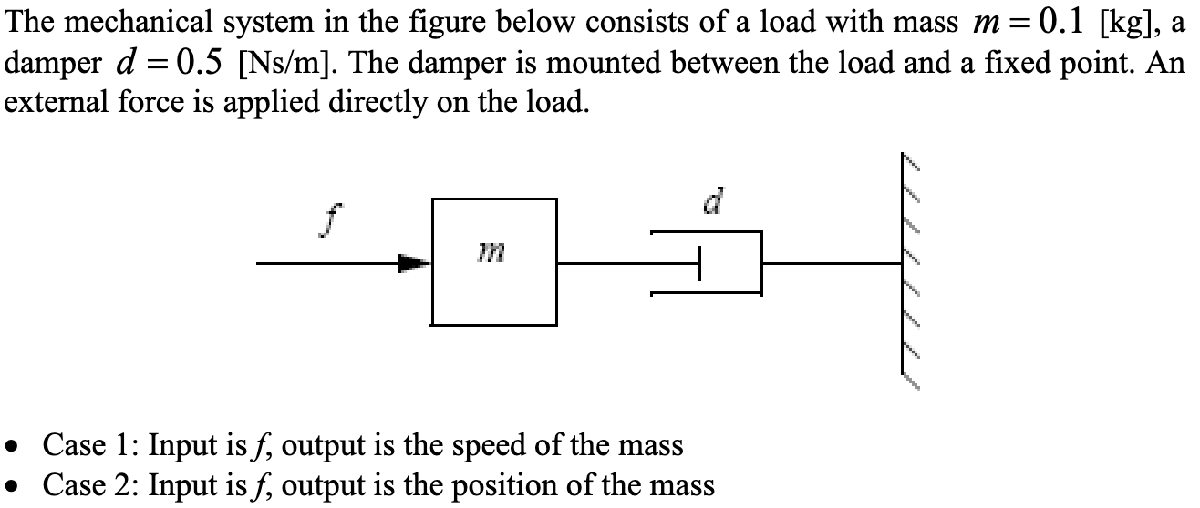

### What is the order of the model if the input is f and the output is the speed of the mass?

In this case the system can be described by the formula: $m \dot{v} = f - dv
$ which can be rewritten as: $\dot{v} + \frac{d}{m} v = \frac{f}{m}
$. The highest derivative of the output here is the first derivative and therefore the model is of order 1.

If the output is the position of the mass, what is the order again?

In this case the system can be described by: $m \ddot{x} = f - d \dot{x}
$ which can be rewritten as: $\ddot{x} + \frac{d}{m} \dot{x} = \frac{f}{m}

$. The highest derivative of the output here is the second derivative and therefore the model is of order 2. 

### Basic parameters

The basic parameters of the system are given in the problem description

m = 0.1; % kg
d = 0.5; % Ns/m

### State space and transfer function models

The state space models and transfer functions were derived on paper according to the following: 

Case 1: 

State space model:


$$% Define the state-space matrices using brackets
A = [\frac{-d}{m}]\ % A matrix (1-by-1)
B = [\frac{1}{m}]\    % B matrix (1-by-1)
C = [1]\      % C matrix (1-by-1, output = v)
D = [0]\      % D matrix (1-by-1)
$$


Transfer function model: 


$$G_1(s) = \frac{1}{m s + d}
$$


% Derived state space model for case 1:

A = -d/m;

B = 1/m;

% u = F

C1 = 1;

D = 0;

sys1 = ss(A, B, C1, D);

% Derived transfer function model for velocity output

s = tf('s');

G1 = 1 / (m*s + d);

Case 2: 

State space model:


$$A = \left( \matrix{0 & 1 \cr 0 & -\frac{d}{m}} \right), \quad
B = \left( \matrix{0 \cr \frac{1}{m}} \right), \quad
C = \left( \matrix{1 & 0} \right), \quad
D = 0
$$


Transfer function model: 


$$G_2(s) = \frac{1}{m s^2 + d s}

$$


% Derived state space model for case 2:

A = [0, 1; 0, -d/m];

B = [0; 1/m];

C2 = [1, 0];

D = 0;

sys2 = ss(A, B, C2, D);

% Derived transfer function model for position output
G2 = 1 / (m*s^2 + d*s);

### Frequency response

The frequency response (bode) for the models is shown below

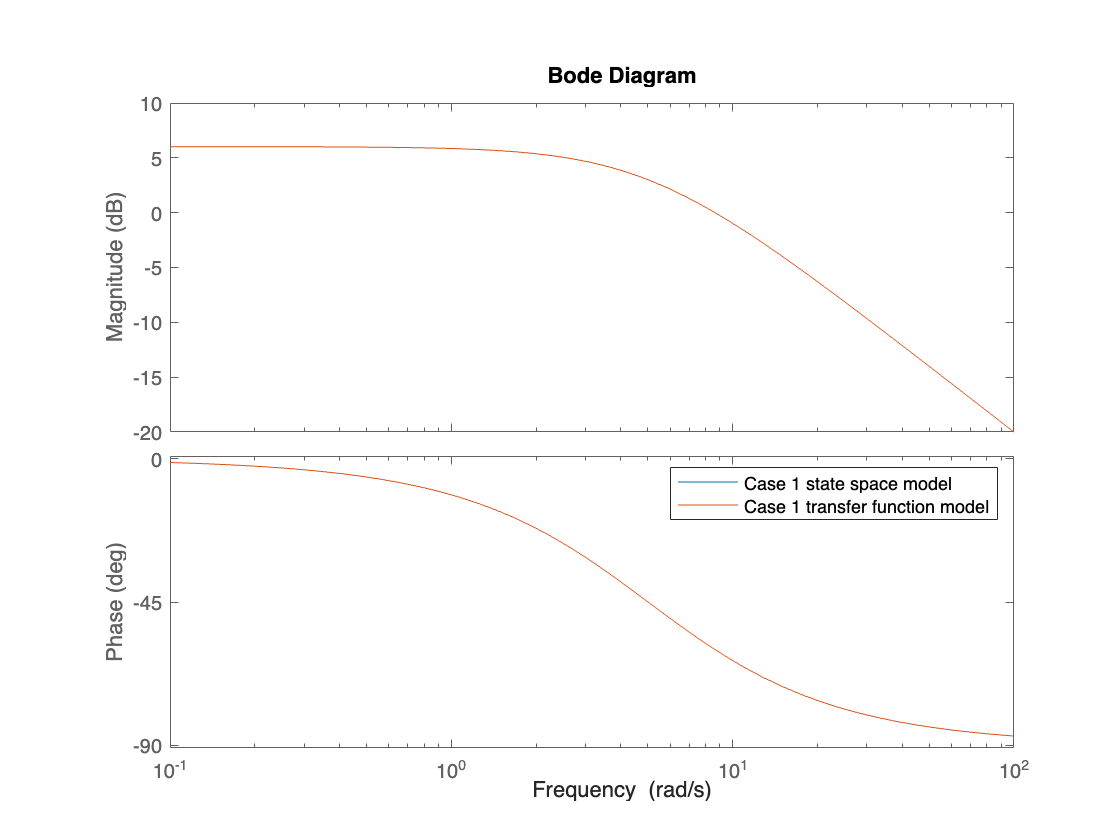

bode(sys1, G1)
legend("Case 1 state space model", "Case 1 transfer function model")
hold off

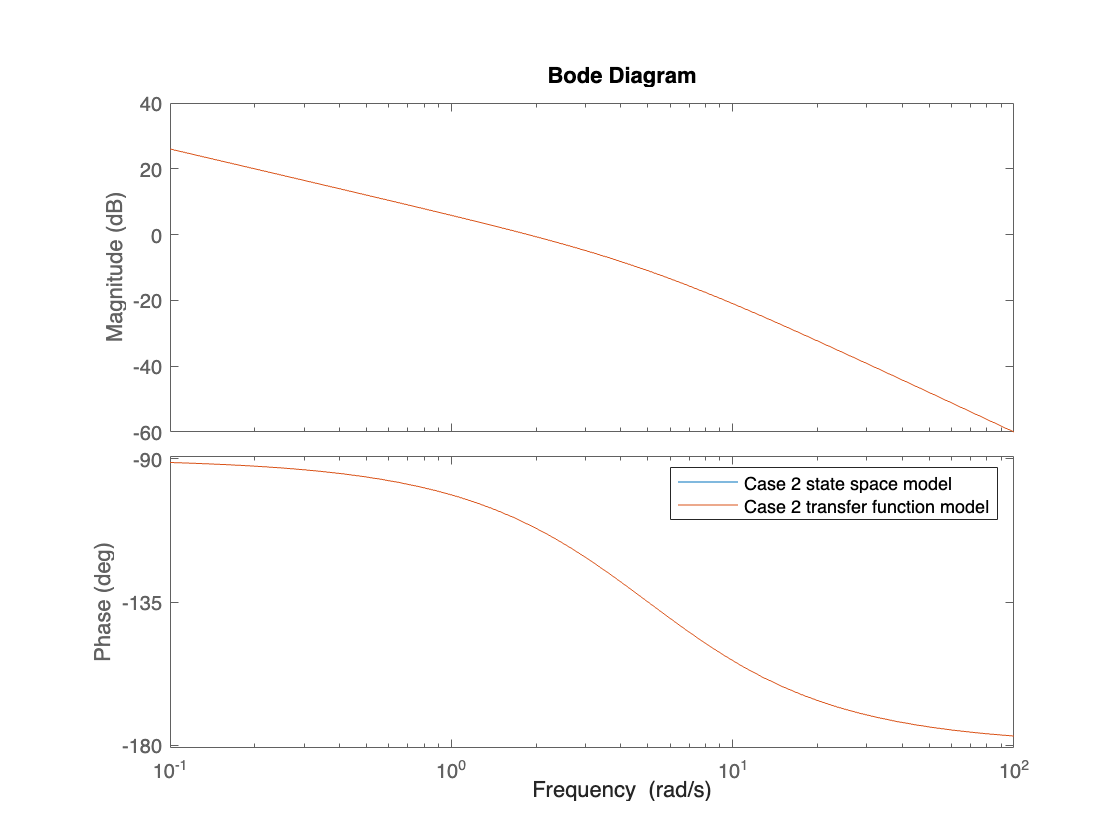

bode(sys2, G2)
legend("Case 2 state space model", "Case 2 transfer function model")

### Step response

The step response of the systems are shown below

Step response of system with velocity as output:

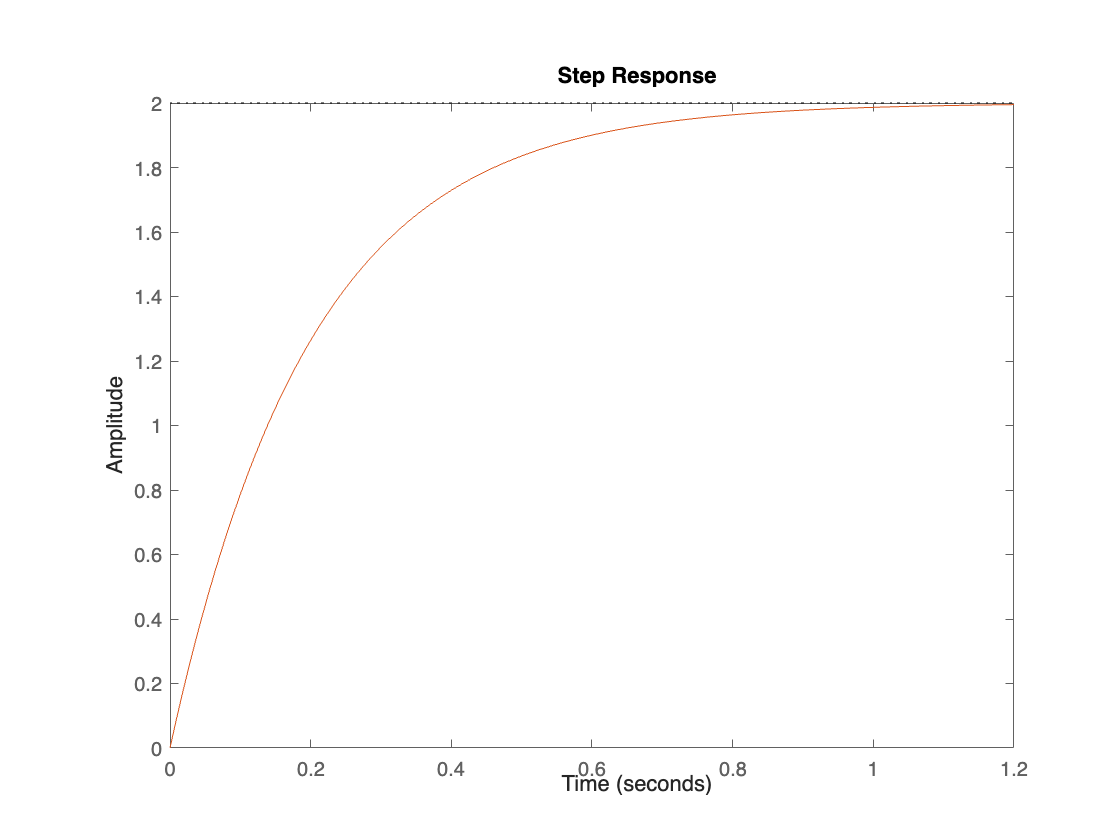


sp =

	resppack.timeplot



sp = stepplot(sys1, G1)

As can be seen in the graph, the amplitude of the velocity reaches a maximum at 2 m/s. This appears feasible. 

Step response of a system with position as output:

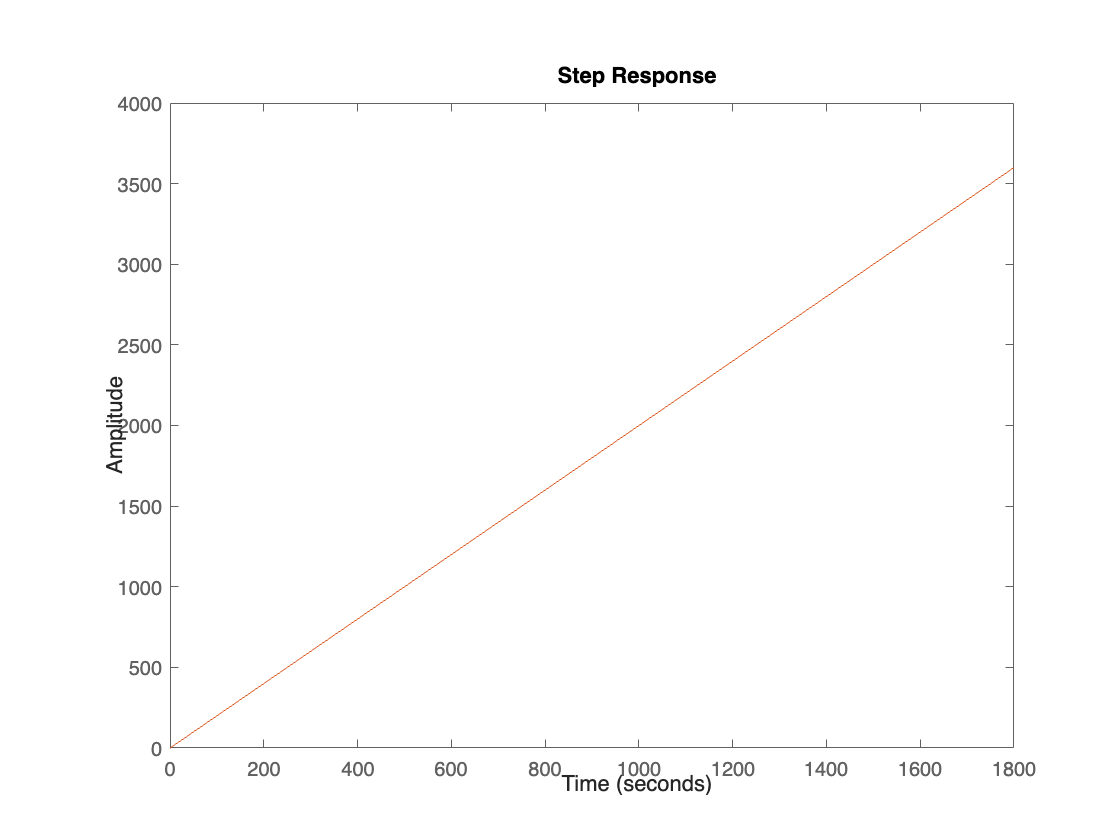


sp2 =

	resppack.timeplot



sp2 = stepplot(sys2, G2)

As can be seen in this graph, the output position magnitude keeps rising linearly. This also appears feasible given that we have a constant positive nonzero amplitude of the velocity after approximately 1,2s. If the velocity is always positive, the position will keep increasing unless some holonomic constraint prevents it from doing so. 

### Pole-zero plots

Furthermore the pole zero plots of the systems were graphed. 

Pole zero plot for system with velocity as output:

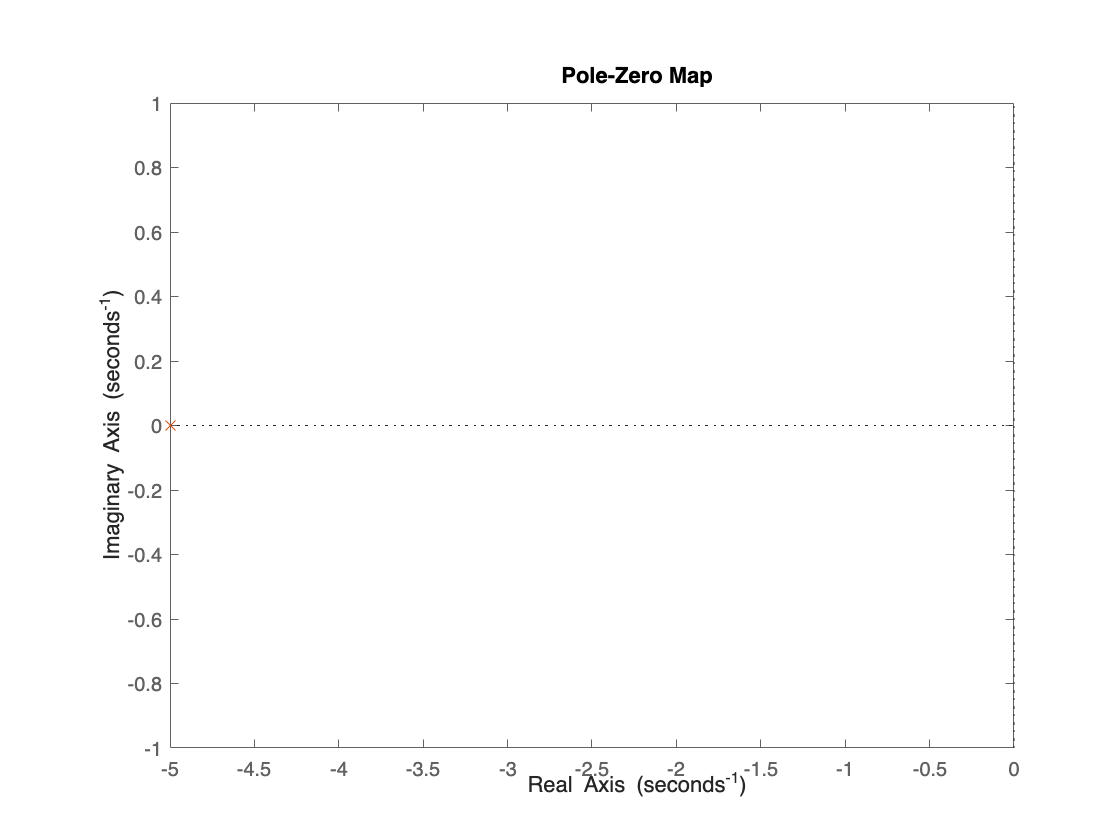


pzp =

	resppack.mpzplot



pzp = pzplot(sys1, G1)

As can be seen in the graph, the system has only one pole on the real axis at -5, and no zeroes. This is also what makes the step response converge to a value as time passes. 

The pole zsero plot of the system with position as output:

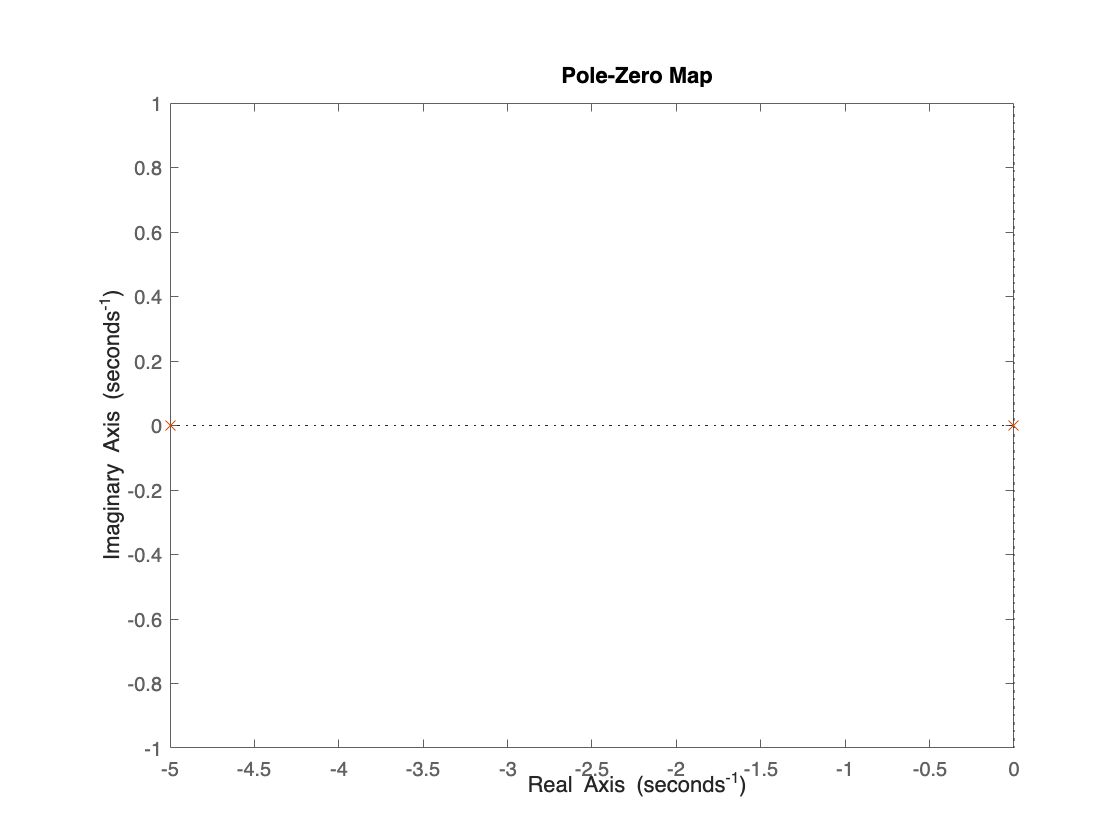


pzp2 =

	resppack.mpzplot



pzp2 = pzplot(sys2, G2)

As can be seen in this graph, the system has two poles, one at -5 and one at 0, the system has no zeroes. This shows that the system is marginally stable, and that in a continous time system the response of the system to a step input will not grow or decay, it will be a ramp. This is specifically the behavior shown in the step response plot for the system with position as output. 

### DC-gain

As can be seen in the step response graphs of the first system with the velocity as output, the amplitude approaches 2 as time increases. The DC-gain of a system is defined in the time domain as $K_{DC} = \lim_{t \to \infty} y(t)
$. In the first system, the graph shows that this DC-gain is 2. 

Calculating the same DC-gain by using the transfer function of the first system and the definition of DC-gain in the s-domain $K_{DC} = G(0) = \lim_{s \to 0} G(s)
$ we find that when inputing $s = 0$ into $G_1(s) = \frac{1}{m s + d}
$ we get $G_1(0) = \frac{1}{d} = 2
$ when d is defined as $d = 0,5 Ns/m$. 

The DC-gain for the second system with the position as output can also be found by studying the step response graph for this system. Here, the graph keeps increasing linearly and does not reach a finite value. Hence, this system has infinite DC-gain. 

Calculating this by using the transfer function of the first system and the definition of DC-gain in the s-domain $K_{DC} = G(0) = \lim_{s \to 0} G(s)
$ we find that when inputing $s = 0$ into $G_2(s) = \frac{1}{m s^2 + d s}

$ we get $G_2(s) = \frac{1}{0} = \infty

$. 

### System time constant

For the first system with velocity as output, the final amplitude value once settled is 2. The time constant is defined as $y(\tau) = 0.632 \, y_{\text{final}} = 1.264
$. Studying the step response graph, this value seems to be reached at approximately $0,2s$. 

Calculating the value can be done by using the formula $\tau = \frac{1}{|\text{Re}(p)|}
$ where p is the systems pole.  With $Re(p) = -5$ as seen in the pole-zero diagram we find that $\tau = 0,2s $ as found in the graph. 

For the second system with position as output, we have no well defined time constant as the system does not reach a final value. The time constant of the system can be said to be $\tau = \infty$.

### Simulink

Transfer function and block diagram model of first system with velocity as output and a step input

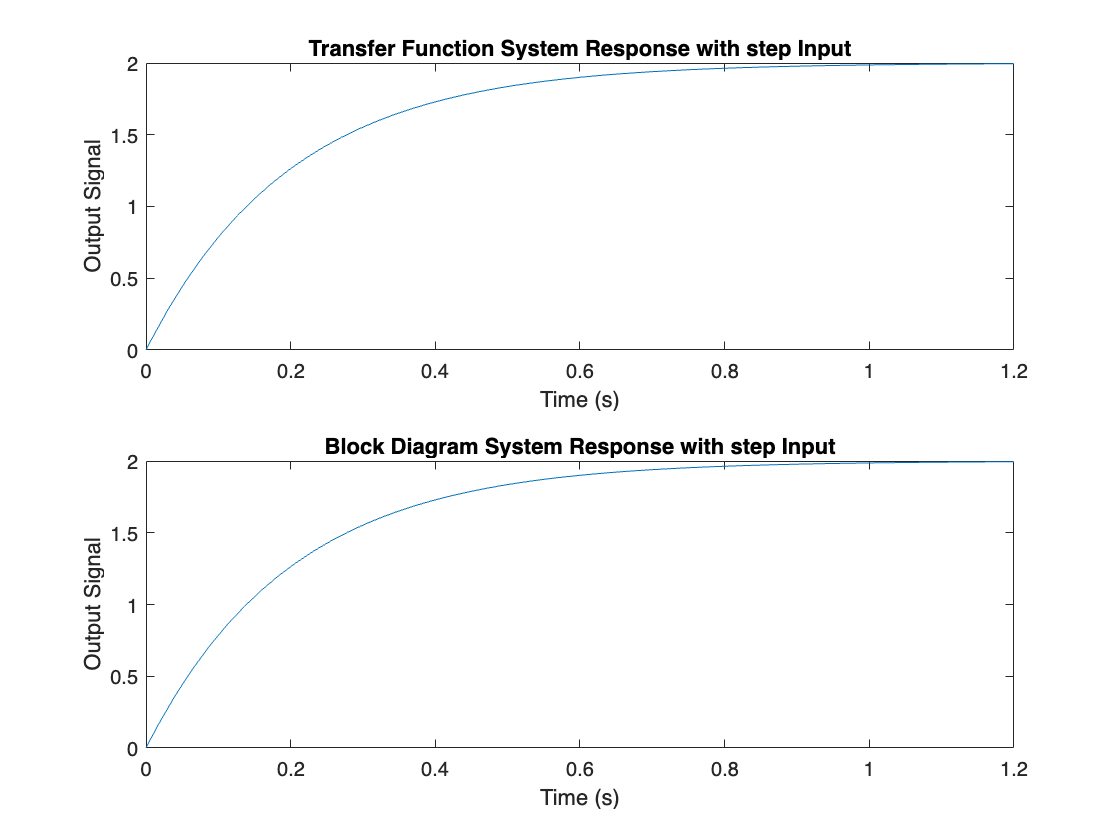


model_name = 'excercise1_tf1'; 
load_system(model_name);


set_param(model_name, 'StopTime', '1.2'); 

% Choose input type: 'step' or 'sine'
input_type = 'step';


switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval'], 'Value', '1');
        
    case 'sine'
        
        set_param([model_name '/switchval'], 'Value', '0');
        
        
        frequency = 1; % Frequency of sine wave in rad/s
        set_param([model_name '/Sine Wave'], 'Frequency', frequency); 
end


simOut = sim(model_name);


sim_time1 = simOut.tout;
output_signal1 = simOut.logsout.getElement('velocity').Values.Data; 


model_name = 'excercise1_bd1'; 
load_system(model_name);


set_param(model_name, 'StopTime', '1.2'); 

% Choose input type: 'step' or 'sine'
input_type = 'step';


switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval'], 'Value', '1');
        
    case 'sine'
        
        set_param([model_name '/switchval'], 'Value', '0');
        
        
        frequency = 1; % Frequency of sine wave in rad/s
        set_param([model_name '/Sine Wave'], 'Frequency', frequency); 
end


simOut = sim(model_name);


sim_time2 = simOut.tout;
output_signal2 = simOut.logsout.getElement('velocity').Values.Data; 

figure;
subplot(2,1,1);
plot(sim_time1, output_signal1);
title(['Transfer Function System Response with ' input_type ' Input']);
xlabel('Time (s)');
ylabel('Output Signal');
subplot(2,1,2);
plot(sim_time2, output_signal2);
title(['Block Diagram System Response with ' input_type ' Input']);
xlabel('Time (s)');
ylabel('Output Signal');

As can be seen from these graphs, the step response of the first system with velocity as output is identical to the step response plotted using the matlab stepplot function. 

Transfer function and block diagram model of second system with position as output and a step input

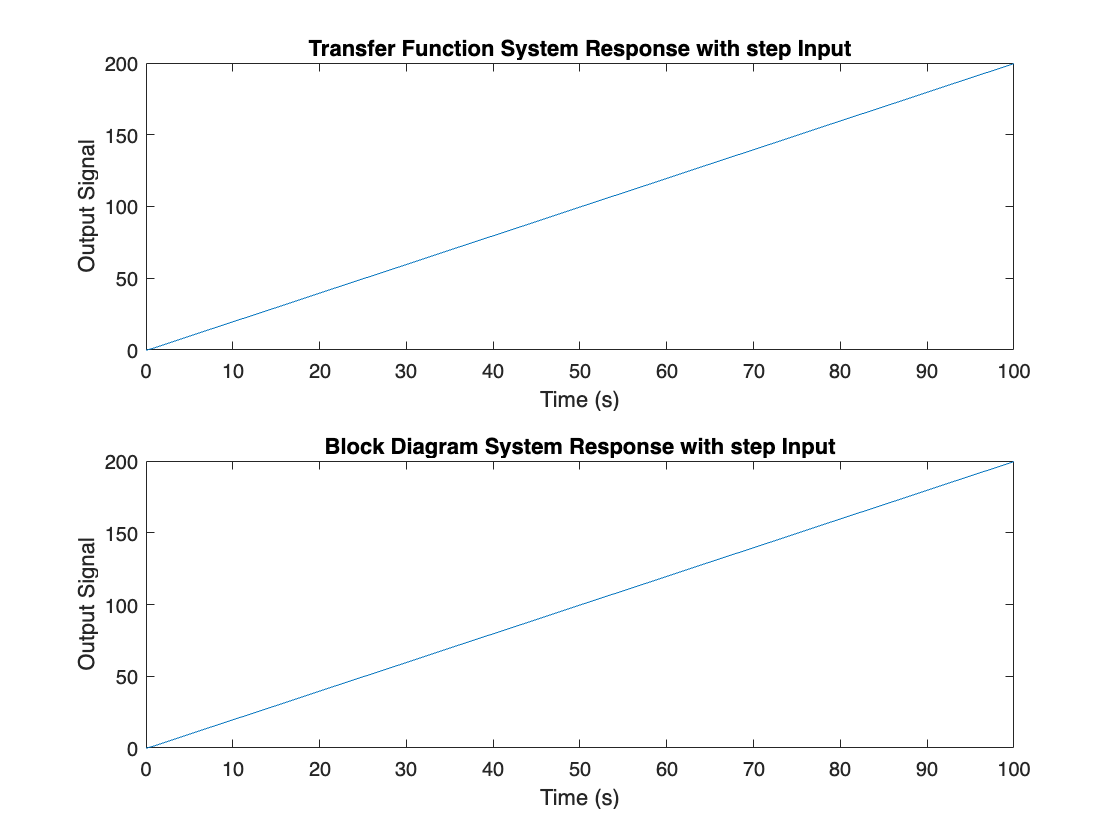


model_name = 'excercise1_tf2'; 
load_system(model_name);


set_param(model_name, 'StopTime', '100'); 

% Choose input type: 'step' or 'sine'
input_type = 'step';


switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval'], 'Value', '1');
        
    case 'sine'
        
        set_param([model_name '/switchval'], 'Value', '0');
        
        
        frequency = 1; % Frequency of sine wave in rad/s
        set_param([model_name '/Sine Wave'], 'Frequency', frequency); 
end


simOut = sim(model_name);


sim_time12 = simOut.tout;
output_signal12 = simOut.logsout.getElement('position').Values.Data; 


model_name = 'excercise1_bd2'; 
load_system(model_name);


set_param(model_name, 'StopTime', '100'); 

% Choose input type: 'step' or 'sine'
input_type = 'step';


switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval'], 'Value', '1');
        
    case 'sine'
        
        set_param([model_name '/switchval'], 'Value', '0');
        
        
        frequency = 1; % Frequency of sine wave in rad/s
        set_param([model_name '/Sine Wave'], 'Frequency', frequency); 
end


simOut = sim(model_name);


sim_time22 = simOut.tout;
output_signal22 = simOut.logsout.getElement('position').Values.Data; 

figure;
subplot(2,1,1);
plot(sim_time12, output_signal12);
title(['Transfer Function System Response with ' input_type ' Input']);
xlabel('Time (s)');
ylabel('Output Signal');
subplot(2,1,2);
plot(sim_time22, output_signal22);
title(['Block Diagram System Response with ' input_type ' Input']);
xlabel('Time (s)');
ylabel('Output Signal');

As can be seen from these graphs, the step response of the second system with position as output is identical to the step response plotted using the matlab stepplot function. 

Transfer function and block diagram model of first system with velocity as output and a sinus input of frequency 1 rad/s

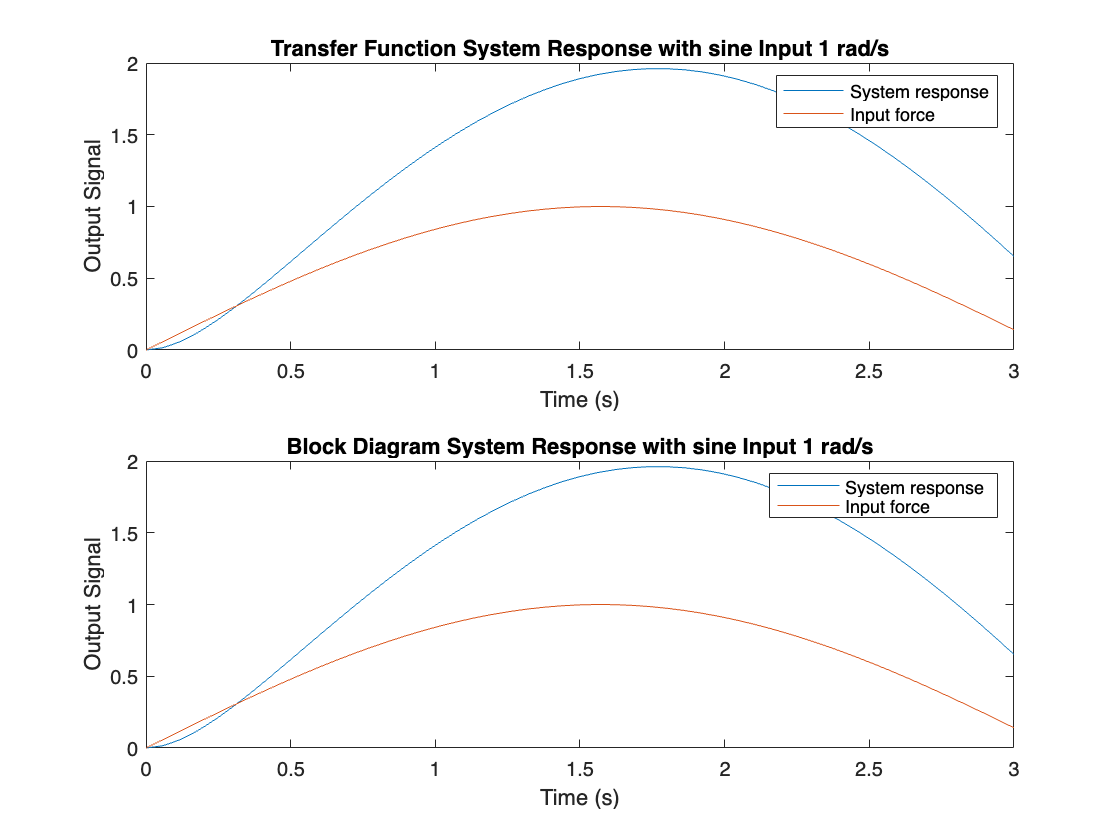


model_name = 'excercise1_tf1'; 
load_system(model_name);


set_param(model_name, 'StopTime', '3'); 

% Choose input type: 'step' or 'sine'
input_type = 'sine';


switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval'], 'Value', '1');
        
    case 'sine'
        
        set_param([model_name '/switchval'], 'Value', '0');
        
        
        frequency = num2str(1); % Frequency of sine wave in rad/s
        set_param([model_name '/Sine Wave'], 'Frequency', frequency); 
end


simOut = sim(model_name);


sim_time13 = simOut.tout;
output_signal13 = simOut.logsout.getElement('velocity').Values.Data; 
input_force13 = simOut.logsout.getElement('force').Values.Data;


model_name = 'excercise1_bd1'; 
load_system(model_name);


set_param(model_name, 'StopTime', '3'); 

% Choose input type: 'step' or 'sine'
input_type = 'sine';


switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval'], 'Value', '1');
        
    case 'sine'
        
        set_param([model_name '/switchval'], 'Value', '0');
        
        
        frequency = num2str(1); % Frequency of sine wave in rad/s
        set_param([model_name '/Sine Wave'], 'Frequency', frequency); 
end


simOut = sim(model_name);


sim_time23 = simOut.tout;
output_signal23 = simOut.logsout.getElement('velocity').Values.Data; 
input_force23 = simOut.logsout.getElement('force').Values.Data;

figure;
subplot(2,1,1);
plot(sim_time13, output_signal13);
title(['Transfer Function System Response with ' input_type ' Input 1 rad/s']);
xlabel('Time (s)');
ylabel('Output Signal');
hold on
plot(sim_time13, input_force13);
legend("System response", "Input force")
hold off

subplot(2,1,2);
plot(sim_time23, output_signal23);
title(['Block Diagram System Response with ' input_type ' Input 1 rad/s']);
xlabel('Time (s)');
ylabel('Output Signal');
hold on
plot(sim_time23, input_force23);
legend("System response", "Input force")
hold off

As can be seen from these graphs, the response of the first system with velocity as output appears to follow the expected behavior. As in the bode diagram, at 1 rad/s there is no major change in amplitude compared to the step response, and the phase shift is relatively minor. 

Transfer function and block diagram model of first system with velocity as output and a sinus input of frequency 10 rad/s

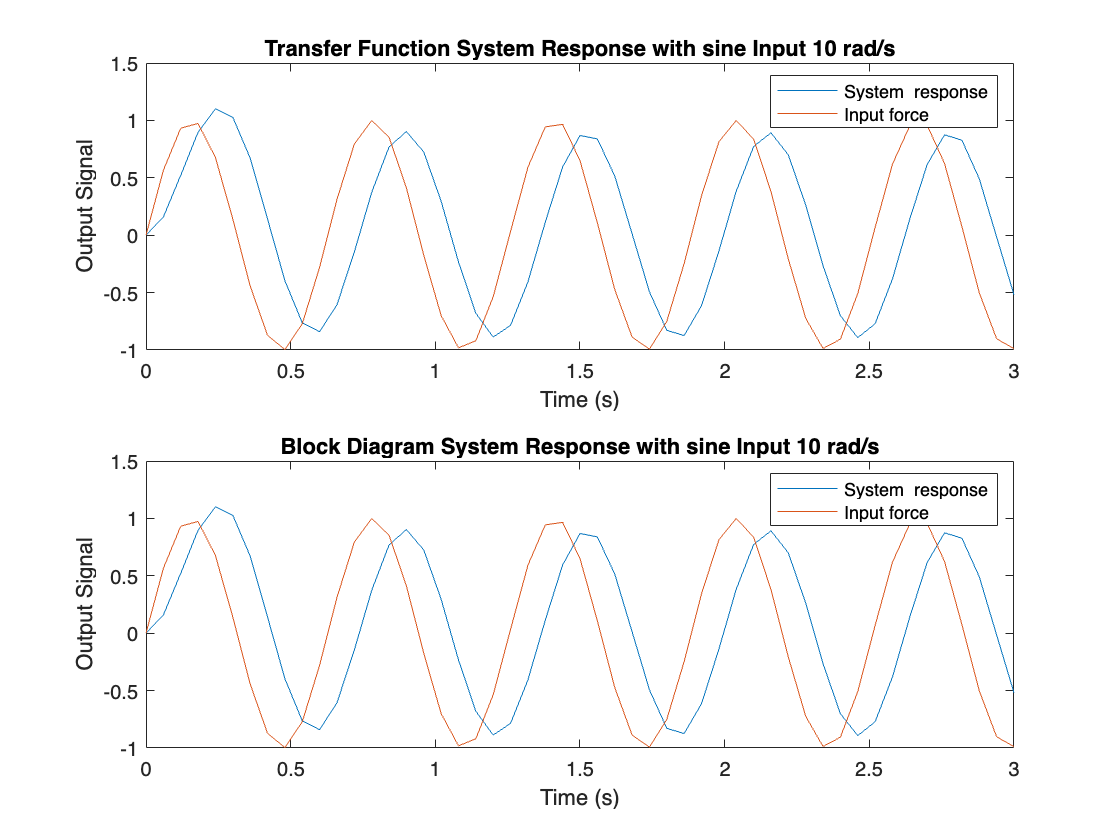

model_name = 'excercise1_tf1';
load_system(model_name);

set_param(model_name, 'StopTime', '3');

% Choose input type: 'step' or 'sine'
input_type = 'sine';

switch input_type
    case 'step'
        set_param([model_name '/switchval'], 'Value', '1');
        
    case 'sine'
        set_param([model_name '/switchval'], 'Value', '0');
        
        frequency = num2str(10);
        set_param([model_name '/Sine Wave'], 'Frequency', frequency);
end


simOut = sim(model_name);


sim_time14 = simOut.tout;
output_signal14 = simOut.logsout.getElement('velocity').Values.Data;
input_force14 = simOut.logsout.getElement('force').Values.Data;

model_name = 'excercise1_bd1'; 
load_system(model_name);

set_param(model_name, 'StopTime', '3'); % 

input_type = 'sine';

switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval'], 'Value', '1');
        
    case 'sine'
        set_param([model_name '/switchval'], 'Value', '0');
        
        frequency = num2str(10); % Frequency of sine wave in rad/s
        set_param([model_name '/Sine Wave'], 'Frequency', frequency);
end

simOut = sim(model_name);

% Retrieve and plot the output
sim_time24 = simOut.tout;
output_signal24 = simOut.logsout.getElement('velocity').Values.Data;
input_force24 = simOut.logsout.getElement('force').Values.Data;

figure;
subplot(2,1,1);
plot(sim_time14, output_signal14);
title(['Transfer Function System Response with ' input_type ' Input 10 rad/s']);
xlabel('Time (s)');
ylabel('Output Signal');
hold on
plot(sim_time14, input_force14);
legend("System  response", "Input force")
hold off

subplot(2,1,2);
plot(sim_time24, output_signal24);
title(['Block Diagram System Response with ' input_type ' Input 10 rad/s']);
xlabel('Time (s)');
ylabel('Output Signal');
hold on
plot(sim_time24, input_force24);
legend("System  response", "Input force")
hold off

As can be seen from these graphs, the response of the first system with velocity as output appears to follow the expected behavior. As in the bode diagram, at 10 rad/s there is a major change in amplitude compared to the step response, going from an amplitude of 2 to an amplitude of approximately 1. The the phase shift is also greater than at 1 rad/s, appearing to be between -45 and -90 degrees. 

Transfer function and block diagram model of second system with position as output and a sinus input of frequency 1 rad/s

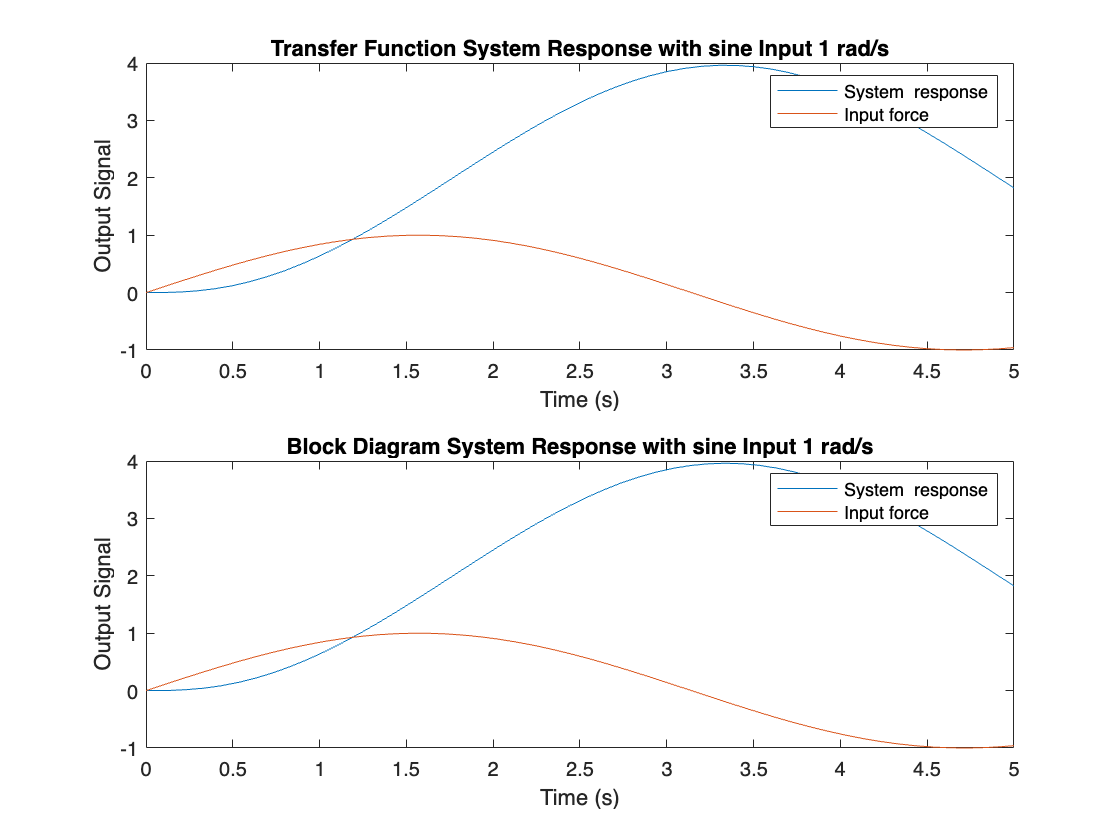


model_name = 'excercise1_tf2'; 
load_system(model_name);


set_param(model_name, 'StopTime', '5'); 

% Choose input type: 'step' or 'sine'
input_type = 'sine';


switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval'], 'Value', '1');
        
    case 'sine'
        
        set_param([model_name '/switchval'], 'Value', '0');
        
        
        frequency = num2str(1); % Frequency of sine wave in rad/s
        set_param([model_name '/Sine Wave'], 'Frequency', frequency); 
end


simOut = sim(model_name);


sim_time15 = simOut.tout;
output_signal15 = simOut.logsout.getElement('position').Values.Data; 
input_force15 = simOut.logsout.getElement('force').Values.Data;


model_name = 'excercise1_bd2'; 
load_system(model_name);


set_param(model_name, 'StopTime', '5'); 

% Choose input type: 'step' or 'sine'
input_type = 'sine';


switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval'], 'Value', '1');
        
    case 'sine'
        
        set_param([model_name '/switchval'], 'Value', '0');
        
        
        frequency = num2str(1); % Frequency of sine wave in rad/s
        set_param([model_name '/Sine Wave'], 'Frequency', frequency); 
end


simOut = sim(model_name);


sim_time25 = simOut.tout;
output_signal25 = simOut.logsout.getElement('position').Values.Data; 
input_force25 = simOut.logsout.getElement('force').Values.Data;

figure;
subplot(2,1,1);
plot(sim_time15, output_signal15);
title(['Transfer Function System Response with ' input_type ' Input 1 rad/s']);
xlabel('Time (s)');
ylabel('Output Signal');
hold on
plot(sim_time15, input_force15);
legend("System  response", "Input force")
hold off

subplot(2,1,2);
plot(sim_time25, output_signal25);
title(['Block Diagram System Response with ' input_type ' Input 1 rad/s']);
xlabel('Time (s)');
ylabel('Output Signal');
hold on
plot(sim_time25, input_force25);
legend("System  response", "Input force")
hold off

As can be seen from these graphs, the response of the second system with position as output appears to follow the expected behavior. As in the bode diagram, at 1 rad/s there is a change in amplitude compared to the step response, with the response approximately doubling. The phase shift is not large but not negligable at a bit over -90 degrees which gives the response peak an apparent offset compared to the input force. 

Transfer function and block diagram model of second system with position as output and a sinus input of frequency 10 rad/s

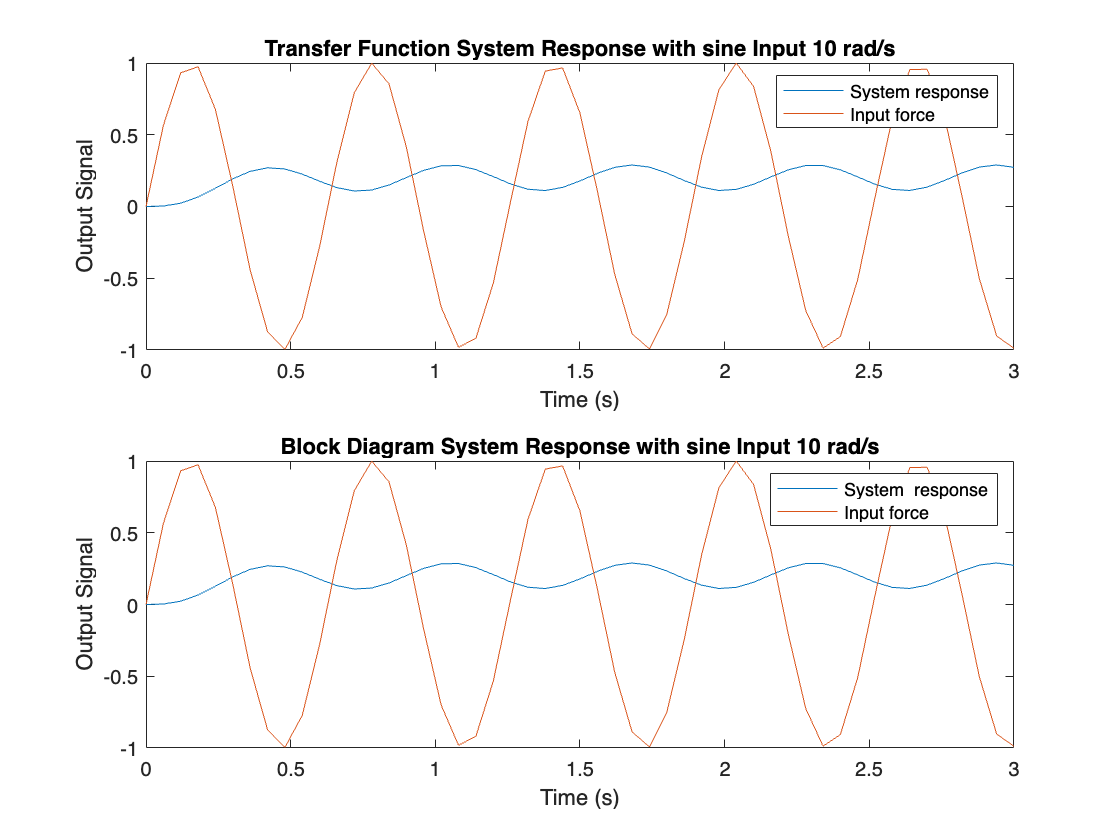

model_name = 'excercise1_tf2';
load_system(model_name);

set_param(model_name, 'StopTime', '3');

% Choose input type: 'step' or 'sine'
input_type = 'sine';

switch input_type
    case 'step'
        set_param([model_name '/switchval'], 'Value', '1');
        
    case 'sine'
        set_param([model_name '/switchval'], 'Value', '0');
        
        frequency = num2str(10);
        set_param([model_name '/Sine Wave'], 'Frequency', frequency);
end


simOut = sim(model_name);


sim_time16 = simOut.tout;
output_signal16 = simOut.logsout.getElement('position').Values.Data;
input_force16 = simOut.logsout.getElement('force').Values.Data;

model_name = 'excercise1_bd2'; 
load_system(model_name);

set_param(model_name, 'StopTime', '3'); % 

input_type = 'sine';

switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval'], 'Value', '1');
        
    case 'sine'
        set_param([model_name '/switchval'], 'Value', '0');
        
        frequency = num2str(10); % Frequency of sine wave in rad/s
        set_param([model_name '/Sine Wave'], 'Frequency', frequency);
end

simOut = sim(model_name);

% Retrieve and plot the output
sim_time26 = simOut.tout;
output_signal26 = simOut.logsout.getElement('position').Values.Data;
input_force26 = simOut.logsout.getElement('force').Values.Data;

figure;
subplot(2,1,1);
plot(sim_time16, output_signal16);
title(['Transfer Function System Response with ' input_type ' Input 10 rad/s']);
xlabel('Time (s)');
ylabel('Output Signal');
hold on
plot(sim_time16, input_force16);
legend("System response", "Input force")
hold off

subplot(2,1,2);
plot(sim_time26, output_signal26);
title(['Block Diagram System Response with ' input_type ' Input 10 rad/s']);
xlabel('Time (s)');
ylabel('Output Signal');
hold on
plot(sim_time26, input_force26);
legend("System  response", "Input force")
hold off

As can be seen from these graphs, the response of the second system with position as output appears to follow the expected behavior. As in the bode diagram, at 10 rad/s there is a very major change in amplitude compared to the step response, going down to an expected value of around 0,2 given the gain of around -20db at that frequency. The the phase shift is also greater than at 1 rad/s, appearing to be between -135 and -180 degrees which places the peaks almost between eatchother.

### Simscape model step response

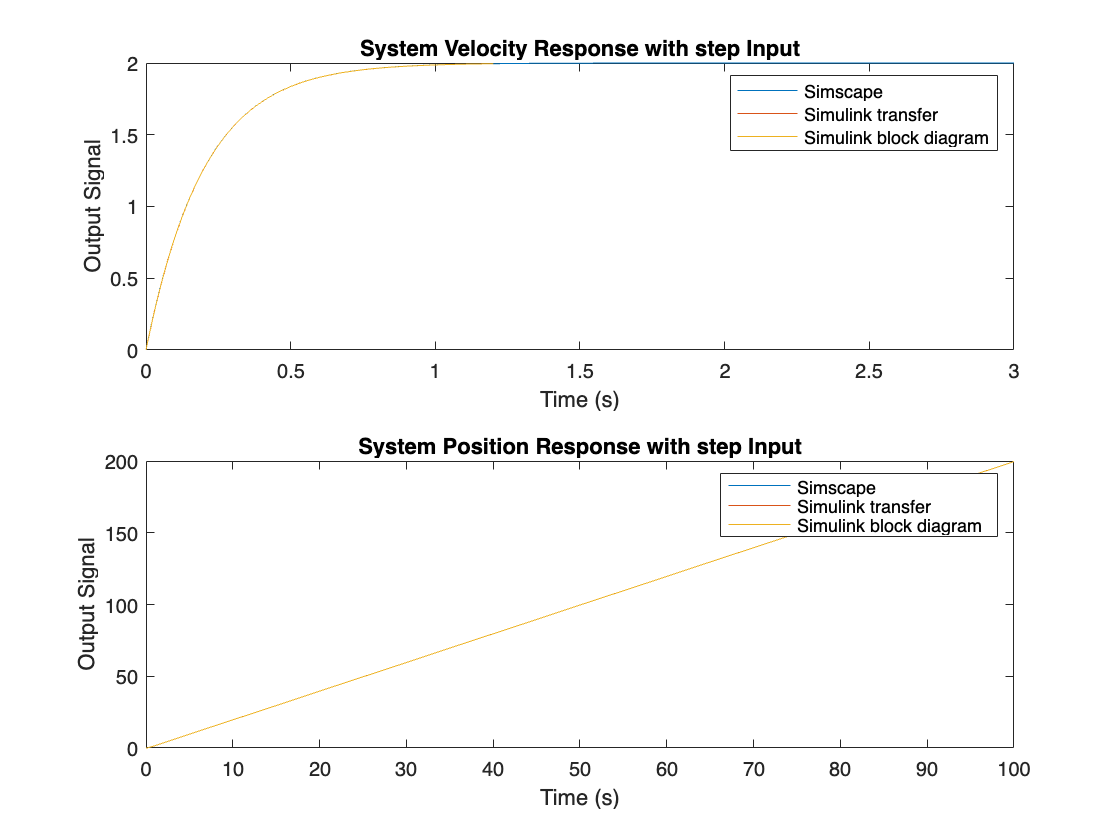

model_name = 'Part1'; 
load_system(model_name);


set_param(model_name, 'StopTime', '3'); 

% Choose input type: 'step' or 'sine'
input_type = 'step';


switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval'], 'Value', '1');
        
    case 'sine'
        
        set_param([model_name '/switchval'], 'Value', '0');
        
        
        frequency = num2str(1); % Frequency of sine wave in rad/s
        set_param([model_name '/Sine Wave'], 'Frequency', frequency); 
end


simOut = sim(model_name);


sim_time17 = simOut.tout;
output_signal17 = simOut.logsout.getElement('Velocity Sim Ex.1').Values.Data; 


model_name = 'Part1'; 
load_system(model_name);


set_param(model_name, 'StopTime', '3'); 

% Choose input type: 'step' or 'sine'
input_type = 'step';


switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval'], 'Value', '1');
        
    case 'sine'
        
        set_param([model_name '/switchval'], 'Value', '0');
        
        
        frequency = num2str(1); % Frequency of sine wave in rad/s
        set_param([model_name '/Sine Wave'], 'Frequency', frequency); 
end


simOut = sim(model_name);


sim_time27 = simOut.tout;
output_signal27 = simOut.logsout.getElement('Position Sim Ex.1').Values.Data; 

figure;
subplot(2,1,1);
plot(sim_time17, output_signal17);
title(['System Velocity Response with ' input_type ' Input']);
xlabel('Time (s)');
ylabel('Output Signal');
hold on
plot(sim_time1, output_signal1);
plot(sim_time2, output_signal2);
legend("Simscape", "Simulink transfer", "Simulink block diagram")
hold off

subplot(2,1,2);
plot(sim_time27, output_signal27);
title(['System Position Response with ' input_type ' Input']);
xlabel('Time (s)');
ylabel('Output Signal');
hold on
plot(sim_time12, output_signal12);
plot(sim_time22, output_signal22);
legend("Simscape", "Simulink transfer", "Simulink block diagram")
hold off

As can be seen from these figures including the output signals from both simscape and also the simulink transfer function and block diagram simulations, we can see that the simscape model returns identical results. Any small deviations are due to the solver and timestep used. 

### Simscape model response with sine wave 1 rad / s 

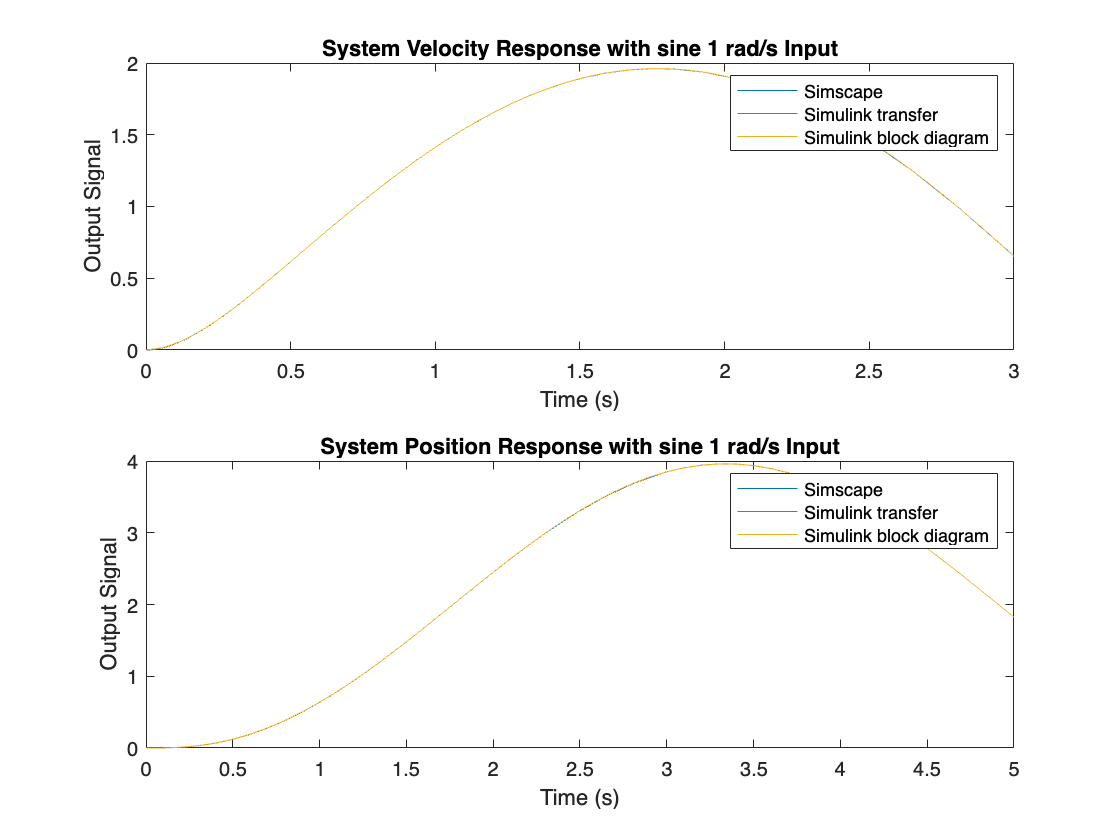

model_name = 'Part1'; 
load_system(model_name);


set_param(model_name, 'StopTime', '3'); 

% Choose input type: 'step' or 'sine'
input_type = 'sine';


switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval'], 'Value', '1');
        
    case 'sine'
        
        set_param([model_name '/switchval'], 'Value', '0');
        
        
        frequency = num2str(1); % Frequency of sine wave in rad/s
        set_param([model_name '/Sine Wave'], 'Frequency', frequency); 
end


simOut = sim(model_name);


sim_time18 = simOut.tout;
output_signal18 = simOut.logsout.getElement('Velocity Sim Ex.1').Values.Data; 


model_name = 'Part1'; 
load_system(model_name);


set_param(model_name, 'StopTime', '3'); 

% Choose input type: 'step' or 'sine'
input_type = 'sine';


switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval'], 'Value', '1');
        
    case 'sine'
        
        set_param([model_name '/switchval'], 'Value', '0');
        
        
        frequency = num2str(1); % Frequency of sine wave in rad/s
        set_param([model_name '/Sine Wave'], 'Frequency', frequency); 
end


simOut = sim(model_name);


sim_time28 = simOut.tout;
output_signal28 = simOut.logsout.getElement('Position Sim Ex.1').Values.Data; 

figure;
subplot(2,1,1);
plot(sim_time18, output_signal18);
title(['System Velocity Response with ' input_type ' 1 rad/s Input']);
xlabel('Time (s)');
ylabel('Output Signal');
hold on
plot(sim_time13, output_signal13);
plot(sim_time23, output_signal23);
legend("Simscape", "Simulink transfer", "Simulink block diagram")
hold off

subplot(2,1,2);
plot(sim_time28, output_signal28);
title(['System Position Response with ' input_type ' 1 rad/s Input']);
xlabel('Time (s)');
ylabel('Output Signal');
hold on
plot(sim_time15, output_signal15);
plot(sim_time25, output_signal25);
legend("Simscape", "Simulink transfer", "Simulink block diagram")
hold off

As can be seen from these figures including the output signals from both simscape and also the simulink transfer function and block diagram simulations, we can see that the simscape model returns identical results. Any small deviations are due to the solver and timestep used. 

### Simscape model response with sine wave 10 rad / s 

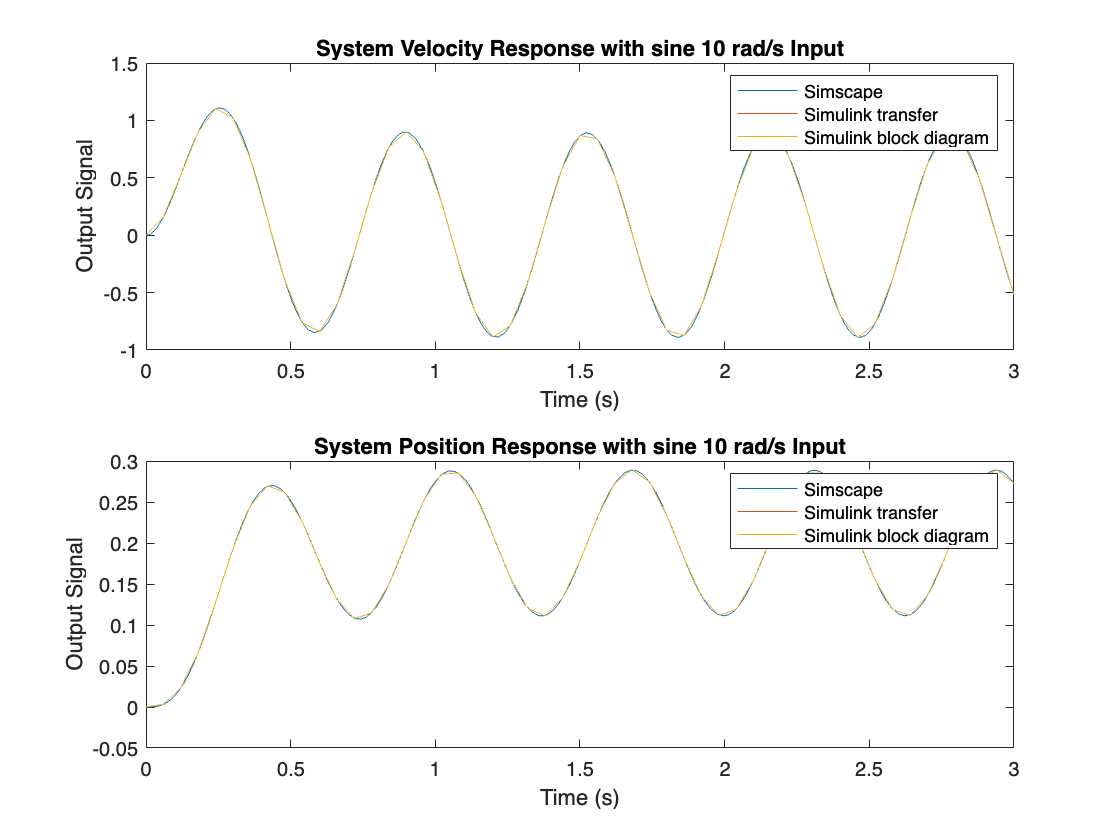

model_name = 'Part1'; 
load_system(model_name);


set_param(model_name, 'StopTime', '3'); 

% Choose input type: 'step' or 'sine'
input_type = 'sine';


switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval'], 'Value', '1');
        
    case 'sine'
        
        set_param([model_name '/switchval'], 'Value', '0');
        
        
        frequency = num2str(10); % Frequency of sine wave in rad/s
        set_param([model_name '/Sine Wave'], 'Frequency', frequency); 
end


simOut = sim(model_name);


sim_time19 = simOut.tout;
output_signal19 = simOut.logsout.getElement('Velocity Sim Ex.1').Values.Data; 


model_name = 'Part1'; 
load_system(model_name);


set_param(model_name, 'StopTime', '3'); 

% Choose input type: 'step' or 'sine'
input_type = 'sine';


switch input_type
    case 'step'
        % Set the switch to Step input (1 for Step, 0 for Sine)
        set_param([model_name '/switchval'], 'Value', '1');
        
    case 'sine'
        
        set_param([model_name '/switchval'], 'Value', '0');
        
        
        frequency = num2str(10); % Frequency of sine wave in rad/s
        set_param([model_name '/Sine Wave'], 'Frequency', frequency); 
end


simOut = sim(model_name);


sim_time29 = simOut.tout;
output_signal29 = simOut.logsout.getElement('Position Sim Ex.1').Values.Data; 

figure;
subplot(2,1,1);
plot(sim_time19, output_signal19);
title(['System Velocity Response with ' input_type ' 10 rad/s Input']);
xlabel('Time (s)');
ylabel('Output Signal');
hold on
plot(sim_time14, output_signal14);
plot(sim_time24, output_signal24);
legend("Simscape", "Simulink transfer", "Simulink block diagram")
hold off

subplot(2,1,2);
plot(sim_time29, output_signal29);
title(['System Position Response with ' input_type ' 10 rad/s Input']);
xlabel('Time (s)');
ylabel('Output Signal');
hold on
plot(sim_time16, output_signal16);
plot(sim_time26, output_signal26);
legend("Simscape", "Simulink transfer", "Simulink block diagram")
hold off

As can be seen from these figures including the output signals from both simscape and also the simulink transfer function and block diagram simulations, we can see that the simscape model returns identical results. Any small deviations are due to the solver and timestep used. 